**The following are symbols in use**

s = tf('s');
syms z;

**The following are the constant varible which will be taken in use**

*See the rapport for how the where determined. Motor 1 (PAN)*

pan_K = 0.5305164;   % Motorconstant (updated)(Men skal det være Nikkies?)
pan_La = 3.362;     % Inductance in mH (updated)
pan_Ra = 10.56;     % Resistance in ohm (updated)
pan_B = 0.00010546342;   % Motor frictions koefficient (updated måske)
pan_J = 0.007047903386363638;     % Motor intertimoment kg*m^2 (updated)

*Motor 2 (TILT)*

tilt_K = 0.5305164;  % Motorconstant (updated)(Men skal det være Nikkies?)
tilt_La = 3.3469;   % Inductance in mH (updated)
tilt_Ra = 8.060;    % Resistance in ohm (updated)
tilt_B = 0.00003226044;% Motor frictions koefficient (updated måske)
tilt_J = 0.05208055730272954;    % Motor intertimoment kg*m^2 (updated) (Men måske meget upræcis)

J_bcs= 0.154400; % Intertimoment for pan/tilt i best kg*m^2 (updated)
J_wcs= 0.150000; % Intertimoment for pan/tilt i worst kg*m^2 (updated)

**The following are the performance specifications**

*It is for the outer loop*

tr_pan = 1;  % Rise time
Mp_pan = 0.1; % Overshoot
ts_pan = 3;   % Settling time

tr_tilt = 1;  % Rise time
Mp_tilt = 0.1; % Overshoot
ts_tilt = 3;   % Settling time

*Below is in freqency domain*

wn_pan = 1.8/tr_pan;
zeta_pan = sqrt(((log(Mp_pan)/-pi)^2)/(1+(log(Mp_pan)/-pi)^2));
sigma_pan = 4.6/ts_pan;

wn_tilt = 1.8/tr_tilt;
zeta_tilt = sqrt(((log(Mp_tilt)/-pi)^2)/(1+(log(Mp_pan)/-pi)^2));
sigma_tilt = 4.6/ts_tilt;

**The following is the three transfer functions**

*Keep in mind they are general expression. Needs to be specified for the motors accordingly.*

*Motor 1 (PAN)*

pan_TF_c =1/(pan_Ra + pan_La*s + ((pan_K*s)/(pan_J*s^2+pan_B*s))); %Current
pan_TF_v =pan_K/((pan_Ra + pan_La)*(pan_J*s+pan_B)+pan_K); %Velocity
pan_TF_p =1/s; %Position


*Motor 2 (TILT)*

tilt_TF_c =1/(tilt_Ra + tilt_La*s + ((tilt_K*s)/(tilt_J*s^2+tilt_B*s))); %Current
tilt_TF_v =tilt_K/((tilt_Ra + tilt_La)*(pan_J*s+tilt_B)+tilt_K)*tilt_Ra; %Velocity
tilt_TF_p =1/s; %Position

**The following is the begining of finding a suitable controller for the system**

Encoder =200 khz ::: ADC_current = 1 mhz  ::: ca 5 gange hurtigere

**Controllability**

*Uses all the constants*

%første tilgang til løsningen
%sysNum = [0 0 K]
%sysDen = [(Ra*J + La*J), (Ra*B + La*B + K) 0]
%sysFrac = tf(sysNum,sysDen) %Der er en afvigelse!
%[A,B,C,D] = tf2ss(sysNum,sysDen)
%controllability = ctrb(A,B)

%A = [0 (K/(J*(Ra+La))); 0 -((Ra*B+La*B+K)/J*(Ra+La))]
%B = [0; (K/(J*(Ra+La)))]
%controllability = ctrb(A,B)
%rank(controllability)

%%andne tilgang til løsningen med afvigelse
% s = tf('s')
% sysLigning = K/(Ra*J*s^2 + La*J*s^2 + Ra*B*s + La*B*s * K*s) %DET ER DET SAMME! (hvilket var meningen)
% sysLigning = tf(sysLigning) %DET ER DET SAMME! (hvilket var meningen)
% sysLigningNum = [0 0 K]
% sysLigningDenum = [0.02096 0.006344 0]
% [A,B,C,D] = tf2ss(sysLigningNum, sysLigningDenum)
%controllability = ctrb(A,B)

**Determining constants for the regulators**

Motor 1 (PAN)

[num_c_pan, den_c_pan] = tfdata(pan_TF_c, 'v'); %For Current
[num_p_pan, den_p_pan] = tfdata(pan_TF_p, 'v'); %For position
[num_v_pan, den_v_pan] = tfdata(pan_TF_v, 'v'); %For velocity

pan_TF_vv =pan_K/((pan_Ra + pan_La)*(pan_J*s+pan_B)+2*pan_K); %Velocity med spændingen som input
[num_vv_pan, den_vv_pan] = tfdata(pan_TF_v, 'v'); %Current

panTF = pan_TF_v*pan_TF_p;
[num_TF_pan, den_TF_pan] = tfdata(panTF, 'v');

%PID controller

%controlSystemDesigner(panTF)
%pidTuner(panTF)

Kp_pan = 8.82;
Ki_pan = 6.64;
Kd_pan = 1.1713;

RegulatorPan=Kd_pan*s+Kp_pan+Ki_pan/s

RegulatorPan =
 
  1.171 s^2 + 8.82 s + 6.64
  -------------------------
              s
 
Continuous-time transfer function.




%LP filter
N_pan = 1000;


*Motor 2 (TILT)*

[num_c_tilt, den_c_tilt] = tfdata(tilt_TF_c, 'v') %For Current

num_c_tilt =          0    0.0521    0.0000         0


den_c_tilt =     0.1743    0.4199    0.5308         0


[num_p_tilt, den_p_tilt] = tfdata(tilt_TF_p, 'v') %For position

num_p_tilt =      0     1


den_p_tilt =      1     0


[num_v_tilt, den_v_tilt] = tfdata(tilt_TF_v, 'v') %For velocity

num_v_tilt =          0    4.2760


den_v_tilt =     0.0804    0.5309



tilt_TF_vv =tilt_K/((tilt_Ra + tilt_La)*(tilt_J*s+tilt_B)+2*tilt_K) %Velocity med spændingen som input

tilt_TF_vv =
 
       0.5305
  ----------------
  0.5941 s + 1.061
 
Continuous-time transfer function.



[num_vv, den_vv] = tfdata(tilt_TF_vv, 'v') %Current

num_vv =          0    0.5305


den_vv =     0.5941    1.0614



tiltTF = tilt_TF_v*tilt_TF_p

tiltTF =
 
          4.276
  ----------------------
  0.08039 s^2 + 0.5309 s
 
Continuous-time transfer function.



[num_TF_tilt, den_TF_tilt] = tfdata(tiltTF, 'v');

%controlSystemDesigner(tiltTF)
%pidTuner(tiltTF)


Kp_tilt = 1.27;
Ki_tilt = 1.1152;
Kd_tilt = 0.1800;

RegulatorTilt=Kd_tilt*s+Kp_tilt+Ki_tilt/s;

%LP filter
N_tilt = 1000;


**Bandwith of system**

%Checks the bandwidth of the system

Closed_loop_pan = RegulatorPan*panTF/(1+RegulatorPan*panTF);
Closed_loop_tilt = RegulatorTilt*tiltTF/(1+RegulatorTilt*tiltTF)

Closed_loop_tilt =
 
        0.06188 s^5 + 0.8452 s^4 + 3.266 s^3 + 2.532 s^2
  -------------------------------------------------------------
  0.006463 s^6 + 0.1472 s^5 + 1.127 s^4 + 3.266 s^3 + 2.532 s^2
 
Continuous-time transfer function.




P = stepinfo(Closed_loop_pan)

P = struct with fields:
        RiseTime: 0.2277
    SettlingTime: 2.1213
     SettlingMin: 0.9198
     SettlingMax: 1.0966
       Overshoot: 9.6568
      Undershoot: 0
            Peak: 1.0966
        PeakTime: 0.5974


T = stepinfo(Closed_loop_tilt)

T = struct with fields:
        RiseTime: 0.1947
    SettlingTime: 1.9037
     SettlingMin: 0.9083
     SettlingMax: 1.0714
       Overshoot: 7.1381
      Undershoot: 0
            Peak: 1.0714
        PeakTime: 0.6241



BoS_pan = bandwidth(Closed_loop_pan)

BoS_pan = 8.3222

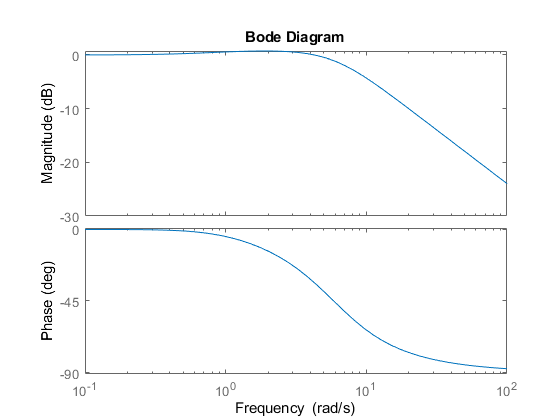


bode_pan =

	resppack.bodeplot



bode_pan = bodeplot(Closed_loop_pan)


BoS_tilt = bandwidth(Closed_loop_tilt)

BoS_tilt = 9.9496

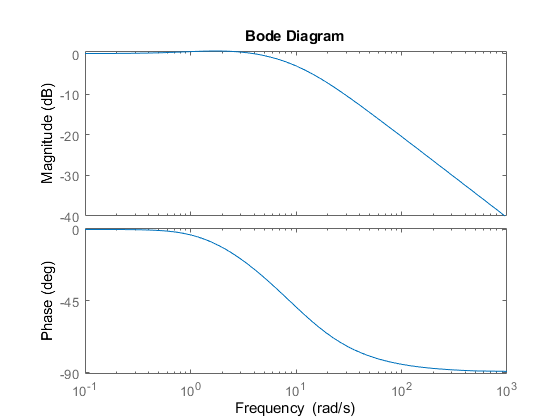


bode_tilt =

	resppack.bodeplot



bode_tilt =bodeplot(Closed_loop_tilt)

**Simulink Data In Graf**

load('PanData.mat')

Error using load
'PanData.mat' is not found in the current folder or on the MATLAB path, but exists in:
    G:\Projekt\RB4-PRO4-Pan-Tilt\Matlab\Nyeste

Change the MATLAB current folder or add its folder to the MATLAB path.

load('TiltData.mat')

%p = stepinfo(PanData)
%t = stepinfo(TiltData)

font_size=20;
width = 50;         
height = 30;
SCREEN_LEFT = 0;
SCREEN_RIGHT = 0;
ADD = 0;
line_width=2;

fig=figure(1);
clf(fig);
hold on
xlabel('Time $t$ [s]','Interpreter','latex','FontSize',font_size)
box on
set(gcf,'Units','centimeters')
%set(gcf,'Position',[SCREEN_LEFT  SCREEN_RIGHT  width+4*ADD  height+2*ADD])
set(gcf,'Color','w')
plot(PanData,'LineWidth',line_width*0.1)
plot(TiltData,'LineWidth',line_width*0.1)

legend('Pan-Controller', 'Tilt-Controller')
set(gca,'FontName','Times New Roman','FontSize',font_size);
%set(gca,'XTickLabel','');
ylabel('Output $y$','Interpreter','latex','FontSize',font_size)

grid on